# ASSIGNMENT 4

Gianpaolo Mastroiacovo(ge28tud)

Antonio Di Giovanni(03743324)

Date()

## Exercise 4.1)

#### *a)*

The constraint (1) enforces each client to be visited only once, as the sum of each row, over all columns, has to be equal to 1, but the row with index $i=0$ is not considered in the constraint, this means that the depot can be visited multiple times (the sum of the row with index $i=0$ will be higher than 1 when the depot is exited multiple times, meaning it has been visited multiple times).

The constraint (2) ensures that the entering and leaving point of each node are equals, meaning that if there is a recorded entrance in the node 5 from node 1 $\left(1,5\right)$, there has to be another record starting from node 5 and going somewhere else $\left(5,x\right)$.

#### *b)*

The constraint $\left(4\right)$ ensures that the quantity delivered to each customer is positive and not larger than the maximum capacity of the vehicle $\bar{V}$. If for a given customer $x_{i,j} =0$, the constraint $\left(5\right)$ forces $q_{i,j}$ to be $\le 0$, but $\left(4\right)$ makes sure that at the same time it is a positive quantity, and the value it will take in this case is exactly 0. In the same way, when $x_{i,j} =1$, according to $\left(5\right)$, $q_{i,j}$ could take any values between 0 and $M$(which is larger than the optimal $\bar{V}$), so $\left(4\right)$ makes sure the maximum value that $q_{i,j}$ can take is exactly $\bar{V}$.

#### *c)*

 The constraint $\left(3\right)$ensures that the quantity delivered to each customer is equal to the demand from that customer. ...

#### *d)*

*Constraint *$\left(3\right)$ forces $q_{i,j}$ to be equal to the $q_{i,j}$ of the previous customer minus the demand for that customer. When all $d_i$ becomes larger than the "remaining" $q_{i,j}$ the only possible move is to go back to the deposit.

*Questions:*

- *What is the level of detail required when doing this exercise? Should we provide examples?*

- *In Exercise 4.2 b), should we re-run the optimization several times or is the question looking for what would be ....*

## Exercise 4.1)

load data_4.2.mat

Capacity = intvar(1);
M=100;
N=length(customer_demands)

N = 15

x = binvar(N+1,N+1,'full'); 
q = sdpvar(N+1,N+1,'full'); % Vedi forum
distances = [N+1,N+1]

distances =     16    16



for i=1:N+1
    for j=1:N+1
        distances (i,j) = sqrt( ((locations(i,1)-locations(j,1))^2) + (((locations(i,2)-locations(j,2))^2) ));
    end
end
%Cons = [];
%for i=1:N+1
%    Cons = [Cons, sum(x(i,:),2) == sum(x(:,i),1)];
%end
Cons =  sum(x,2) == transpose(sum(x,1));
Cons = [Cons, sum(x(2:end,:),2) == 1];

%for i=2:N+1
%    Cons = [Cons, sum(q(:,i),1) - sum(q(i,:),2) == customer_demands(i-1)];
%end
Cons = [Cons, transpose(sum(q(:,2:end),1)) - sum(q(2:end,:),2) == customer_demands];
Cons = [Cons, q >= 0];
Cons = [Cons, q <= Capacity];
Cons = [Cons, q <= x .* M];


obj = vehicle_cost * Capacity +  (travel_cost * sum(distances .* x,"all"))

Linear scalar (real, integer, 241 variables)
Coefficients range: 0.060229 to 0.98583



ops = sdpsettings('solver', 'gurobi', 'verbose', 0);

Result = optimize(Cons, obj, ops);

value(q)

ans =          0         0   24.6529   22.3801         0   28.0000   28.0000         0         0         0         0   28.0000         0   22.7815   23.7595         0
    2.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0   12.1097         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    8.8603         0         0         0         0         0         0         0         0
         0   14.6503         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0   19.7423         0         0         0         0         0         0         0         0         0         0         0
         0         0        

value(x) 

ans =      1     0     1     1     0     1     1     0     0     0     0     1     0     1     1     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


value(obj) 

ans = 8.4381

value(Capacity)

ans = 28

b)

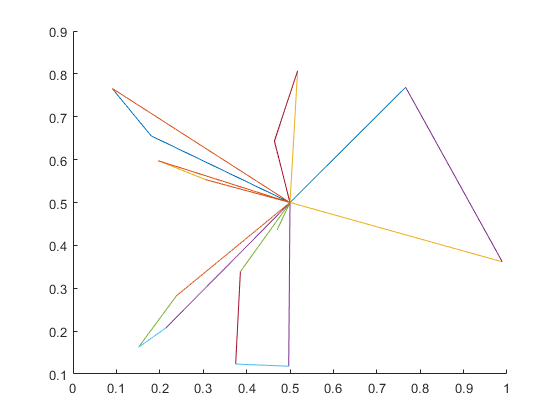

%scatter(locations(:,1),locations(:,2))

%Usa ciclo for con if se x_ij == 1
hold on 
for i=1:N+1
    for j=1:N+1
        if(value(x(i,j))==1)    
            plot(locations([i,j],1),locations([i,j],2))
        end
    end
end
hold off

c)

load data_4.2.mat

Capacity = intvar(1);
T = intvar(1);
M=100;
N=length(customer_demands)

N = 15

x = binvar(N+1,N+1,'full'); 
q = sdpvar(N+1,N+1,'full'); % Vedi forum
distances = [N+1,N+1]

distances =     16    16



for i=1:N+1
    for j=1:N+1
        distances (i,j) = sqrt( ((locations(i,1)-locations(j,1))^2) + (((locations(i,2)-locations(j,2))^2) ));
    end
end

Cons =  sum(x,2) == transpose(sum(x,1));
Cons = [Cons, sum(x(2:end,:),2) == 1];
Cons = [Cons, transpose(sum(q(:,2:end),1)) - sum(q(2:end,:),2) == customer_demands];
Cons = [Cons, q >= 0];
Cons = [Cons, q <= Capacity];
Cons = [Cons, q <= x .* M];
Cons = [Cons, T == sum(x(1,:),2)];

cTau = [];
nTravels = [];
objective = [];

for i=0:0.2:1
c_tau = i;
obj = vehicle_cost * Capacity +  (travel_cost * sum(distances .* x,"all") + c_tau*T)

ops = sdpsettings('solver', 'gurobi', 'verbose', 0);

Result = optimize(Cons, obj, ops);
cTau = [cTau, c_tau];
nTravels = [nTravels, T];
objective = [objective, value(obj)];
end

Linear scalar (real, integer, 241 variables)
Coefficients range: 0.060229 to 0.98583
Linear scalar (real, integer, 242 variables)
Current value: 10.0381
Coefficients range: 0.060229 to 0.98583
Linear scalar (real, integer, 242 variables)
Current value: 10.5935
Coefficients range: 0.060229 to 0.98583
Linear scalar (real, integer, 242 variables)
Current value: 11.3311
Coefficients range: 0.060229 to 0.98583
Linear scalar (real, integer, 242 variables)
Current value: 11.9256
Coefficients range: 0.060229 to 0.98583
Linear scalar (real, integer, 242 variables)
Current value: 12.5256
Coefficients range: 0.060229 to 1


value(T)

ans = 3

value(obj)

ans = 12.8256

value(x)

ans =      0     0     1     0     0     0     0     0     0     0     1     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


cTau

cTau =     0.1000    0.3000    0.5000    0.7000    0.9000    1.1000


Conclusions about how the solution changes:

...

## Exercise 4.1)

a)


$$\begin{array}{l}
\min_{x,\bar{V} ,q} \;\;\;\;\;c^V \bar{V} +S^{-1} \sum_{s\;\in \;S} \left.{p_s \left(c\right.}^T {\left\|l_i -l_j \right\|}_2 x_{i\ldotp j}^s +c^{\tau \;} T^s \right)\\
\\
s\ldotp t\ldotp \;\;\;\\
\sum_{j=0}^N {x^s }_{i,j} \;=\sum_{k=0}^N {x^s }_{k,i} \;\;\;\;\;\;\;\forall i:0\le i\le N,\forall s\in S\\
\sum_{j=0}^N {x^s }_{i,j} =0\;\;\;\;\;\;\;\;\forall i:1\le i\le N,\forall s\in S\\
\sum_{j=0}^N {q^s }_{i,j} -\sum_{k=0}^N {q^s }_{k,i} ={d^s }_i \;\;\;\;\;\;\forall i:1\le i\le N,\;\forall s\in S\\
0\le q_{i,j}^s \le \bar{V} \;\;\;\;\;\;\;\;\;\forall i,j:0\le i,j\le N,\forall s\in S\\
q_{i,j}^s \le x_{i,j}^s M\;\;\;\;\;\;\;\;\;\;\;\forall i,j:0\le i,j\le N\ldotp \forall s\in S\\
x_{i,j}^s \in \left\lbrace 0,1\right\rbrace \;\;\;\;\;\;\;\;\;\;\forall i,j:0\le i,j\le N\ldotp \forall s\in S\\
\bar{V} \in \aleph \\

\end{array}$$


b)

clear;
load data_4.3.mat

%c_tau = 0.2;
[N,S] = size(demand_scen);
Capacity = intvar(1);
T = intvar(1,S);
M=100;
x = binvar(N+1,N+1,S, 'full'); 
q = sdpvar(N+1,N+1,S, 'full'); 
distances = [N+1,N+1];

for i=1:N+1
    for j=1:N+1
        distances (i,j) = sqrt( ((locations(i,1)-locations(j,1))^2) + (((locations(i,2)-locations(j,2))^2) ));
    end
end

Cons =  sum(x,2) == transpose(sum(x,1));
for s=1:S
Cons = [Cons, sum(x(2:end,:,s),2) == 1];
Cons = [Cons, transpose(sum(q(:,2:end,s),1)) - sum(q(2:end,:,s),2) == demand_scen(:,s)];
end
Cons = [Cons, q >= 0];
Cons = [Cons, q <= Capacity];
Cons = [Cons, q <= x .* M];
Cons = [Cons, T == sum(x(1,:),2)];

for i=1:S
    distances(:,:,i) = distances(:,:,1);
end

obj = vehicle_cost * Capacity +  mean((fixed_tour_cost * sum(distances .* x,"all") + c_tau*T));

%ops = sdpsettings('solver', 'gurobi', 'verbose', 0);
%Change the 0.5 to 0.2 or 0.1
ops = sdpsettings ( 'solver','gurobi', 'gurobi.MIPGap',0.5);
Result = optimize(Cons, obj, ops);

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 3290 rows, 2011 columns and 10330 nonzeros
Model fingerprint: 0x7709bac1
Variable types: 1000 continuous, 1011 integer (1000 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [2e-02, 3e-01]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Presolve removed 1210 rows and 210 columns
Presolve time: 0.05s
Presolved: 2080 rows, 1801 columns, 11106 nonzeros
Variable types: 900 continuous, 901 integer (900 binary)
Found heuristic solution: objective 35.1299731

Root relaxation: objective 1.384387e+01, 1371 iterations, 0.03 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0   13.84387    0  236   35.1299

Test 2 for stochastic problem:

clear;
load data_4.3.mat

[N,S] = size(demand_scen);
Capacity = intvar(1);
T = intvar(1,S);
M=100;
x = binvar(N+1,N+1,S, 'full'); 
q = sdpvar(N+1,N+1,S, 'full'); 


Cons =  sum(x,2) == transpose(sum(x,1));
for s=1:S
Cons = [Cons, sum(x(2:end,:,s),2) == 1];
Cons = [Cons, transpose(sum(q(:,2:end,s),1)) - sum(q(2:end,:,s),2) == demand_scen(:,s)];
Cons = [Cons, T(:,s) == sum(x(1,:,s),2)];
Cons = [Cons, q(:,:,s) >= 0];
Cons = [Cons, q(:,:,s) <= Capacity];
Cons = [Cons, q(:,:,s) <= x(:,:,s) .* M];
end

obj = vehicle_cost * Capacity +  mean(fixed_tour_cost .* T);

ops = sdpsettings ( 'solver','gurobi', 'gurobi.MIPGap',0.2);

Result = optimize(Cons, obj, ops);

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 3290 rows, 2011 columns and 9430 nonzeros
Model fingerprint: 0x974c1794
Variable types: 1000 continuous, 1011 integer (1000 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [2e-02, 3e-01]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Presolve removed 1210 rows and 210 columns
Presolve time: 0.04s
Presolved: 2080 rows, 1801 columns, 10940 nonzeros
Variable types: 900 continuous, 901 integer (900 binary)
Found heuristic solution: objective 6.8800000

Root relaxation: objective 5.625576e+00, 1161 iterations, 0.02 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    5.64301    0  206    6.88000 

c)

Solving the averager:

customer_demands = mean(demand_scen,2);
Capacity = intvar(1);
T = intvar(1);
M=100;
N=length(customer_demands)

N = 9

x = binvar(N+1,N+1,'full'); 
q = sdpvar(N+1,N+1,'full'); % Vedi forum

Cons =  sum(x,2) == transpose(sum(x,1));
Cons = [Cons, sum(x(2:end,:),2) == 1];
Cons = [Cons, transpose(sum(q(:,2:end),1)) - sum(q(2:end,:),2) == customer_demands];
Cons = [Cons, q >= 0];
Cons = [Cons, q <= Capacity];
Cons = [Cons, q <= x .* M];
Cons = [Cons, T == sum(x(1,:),2)];

obj = vehicle_cost * Capacity +  fixed_tour_cost .* T;

%Same solution with both settings
ops = sdpsettings('solver', 'gurobi', 'verbose', 0);
%ops = sdpsettings ( 'solver','gurobi', 'gurobi.MIPGap',0.2);

Result = optimize(Cons, obj, ops);